**EE 699 Next Generation Wireless Networks Assignment 01**

% Simulation constants 
n_runs = 1 ;

% Parameter Constants 
N_fft = 128 ;          % Size of the FFT
del_F = 15 * 10 ^ 3 ;  % Sub carrier spacing 
Fs = N_fft * del_F ;   % Sampling Rate
num_rf = 1 ;           % Number of Radio Frames
t_sample = 1 / del_F;  % Duration of one FFT sample

num_sf = num_rf * 10 ;
num_slots = num_sf * 2 ;

% Force Number of Subframes :
num_sf = 1 ;

% Time axes calculations :
slot_duration = 0.5 * 10 ^ -3 ;
subf_duration = 2 * slot_duration ;
rf_duration = 10 * subf_duration ;
total_duration = num_sf * subf_duration ;

t_axes = 0: 1/Fs: total_duration - (1/Fs) ;

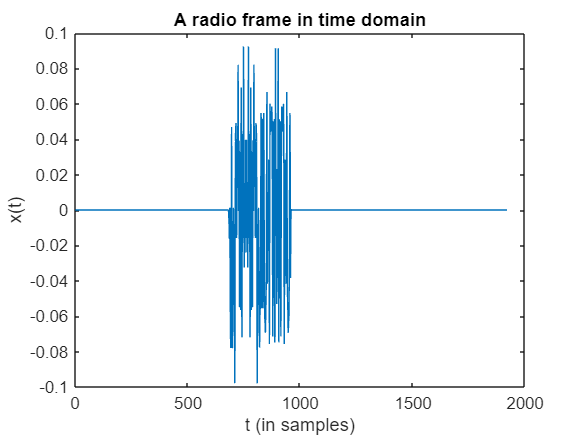

% Demo of the generated signals in time domain 
x_t = LTEsignalGen(num_sf) ;
plot(real(x_t)) ;
xlabel('t (in samples)') ;
ylabel('x(t)')
title('A radio frame in time domain') ;

% Creation of reference signals in frequency domain :
[time_refPSS, time_refSSS] = refSignalGen("time") ;
[freq_refPSS, freq_refSSS] = refSignalGen("frequency") ;

- a. PSS Detection - Using time domain and frequency domain correlation 

% Simulation routine
T0 = [] ;
F0 = [] ;
P_PSS_ID = [] ;
P_SSS_ID = [] ;

lowlimit = -2 ;
uplimit = 15 ;
% Varying the SNR from -2 to 10 dB
% for SNR_dB = lowlimit:uplimit
    SNR_lin = 10 ^ (SNR_dB / 10) ;
    % Do multiple runs
    t0 = 0 ;
    f0 = 0 ;
    count_pss_ID = 0 ;
    count_sss_ID = 0 ;
    for run_id = 0: n_runs-1
        % Add a time offset
        t_off_ideal = randi(9) 
        [x_t, truPSSid, truSSSid] = LTEsignalGen(1) ;
        x_t
        x_t = [zeros(t_off_ideal, 1); x_t] ;
            
        % Channel Reponse : AWGN Channel 
        mu = 0 ;
        sig2 = (1 / (2 * SNR_lin)) ;
        % noise_samples_1 = normrnd(mu, sig2, size(x_t)) + 1j * normrnd(mu, sig2, size(x_t)) ;
        % noise_samples_2 = normrnd(mu, sig2, size(x_t)) + 1j * normrnd(mu, sig2, size(x_t)) ;
        % Received signal y(t) :
        % y_t_1 = x_t + noise_samples_1 ;
        % y_t_2 = x_t + noise_samples_2 ;
        % y_t = y_t_1 + y_t_2 ;
        y_t = x_t ;
        % Add a frequency offset
        f_off_ideal = randi([-200, 200]) ;
        shift_factor = exp(1j * 2 * pi * f_off_ideal) ;
        for n=1:length(y_t)
            y_t(n) = shift_factor ^ (n) * y_t(n) ;
        end

        % Detection of PSS ID using time domain correlation and finding the time offset in number of samples
        estPSSID = 0 ;
        [c, lags] = xcorr(y_t, time_refPSS(:, 1)) ;
        [currPeak, maxInd] = max(abs(c)) ; 
        currTimeoff = lags(maxInd) ;
        for idx=2:3 
          [c, lags] = xcorr(y_t, time_refPSS(:, idx)) ;
          [nxtPeak, maxInd] = max(abs(c)) ; 
          nxtTimeoff = lags(maxInd) ;
          if nxtPeak > currPeak 
              estPSSID = idx - 1;
              currPeak = nxtPeak ;
              currTimeoff = nxtTimeoff ;
          end
        end
        % Analysis of detection 
        if (estPSSID ~= truPSSid)
            count_pss_ID = count_pss_ID + 1 ;
        end
        t_off_est = currTimeoff ;
        
        timeError = (t_off_ideal - t_off_est) ^ 2 ;
        t0 = t0 + timeError ;

        % Detection of the PSS ID using frequency domain correlation and
        % finding the frequency offset:
        % Time offset correction :
        y_t_offCorrect = y_t(t_off_est+1:length(y_t), 1) ;
        
        % Cyclic Prefix Removal :
        % 0th and 7th symbol == 10 samples ; Others == 9 samples 
        r_t = [] ;
        temp_ind = 1 ;
        for i = 1: 14 
            if mod(i, 7) == 0 
                temp_ind = temp_ind + 10 ;
                r_t = [r_t y_t_offCorrect(temp_ind:temp_ind+N_fft-1, 1)] ;
                temp_ind = temp_ind + N_fft ;
            else
                temp_ind = temp_ind + 9 ;
                r_t = [r_t y_t_offCorrect(temp_ind:temp_ind+N_fft-1, 1)] ;
                temp_ind = temp_ind + N_fft ; 
            end
        end
        R = [] ;
        for i = 1: 14
            R = [R fft(r_t(:, i))] ;
        end
        enb.NDLRB = 6;                      % Number of resource blocks
        enb.CellRefP = 1;                   % One transmit antenna port
        enb.NCellID = 3*truSSSid + truPSSid;    % Cell ID
        enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
        enb.DuplexMode = 'FDD';             % FDD
        for me=1:35
            me
            R(1+me:72+me, :) == lteOFDMDemodulate(enb, y_t_offCorrect)
        end
        % freqError = (f_off_ideal - f_off_est) ^ 2 ;
        % f0 = f0 + freqError ;
    end

t_off_ideal = 5

x_t =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


me = 1

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 2

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 3

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 4

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 5

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 6

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 7

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 8

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 9

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 10

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 11

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 12

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 13

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 14

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 15

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 16

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 17

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 18

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 19

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 20

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 21

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 22

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 23

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 24

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 25

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 26

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 27

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 28

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 29

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 30

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 31

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 32

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 33

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 34

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


me = 35

ans = 72×14 logical array
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1
   1   1   1   1   0   0   0   1   1   1   1   1   1   1


    P_PSS_ID = [P_PSS_ID (count_pss_ID / n_runs)] ;
    T0 = [T0 (t0 / n_runs)] ;
    F0 = [F0 (f0 / n_runs)] ;
% end

**Plots for visualization of PSS Detection :**

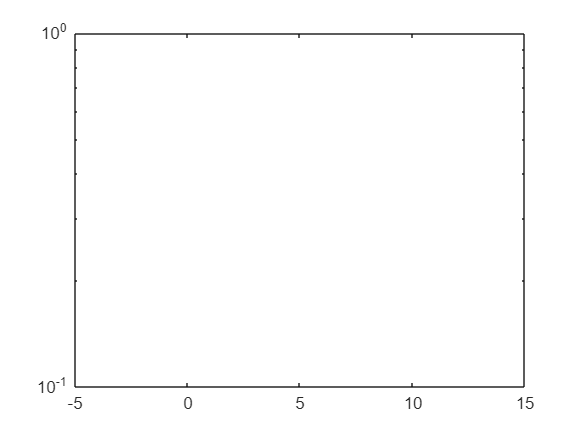

SNR_range = lowlimit:uplimit ;

semilogy(SNR_range, T0) ;

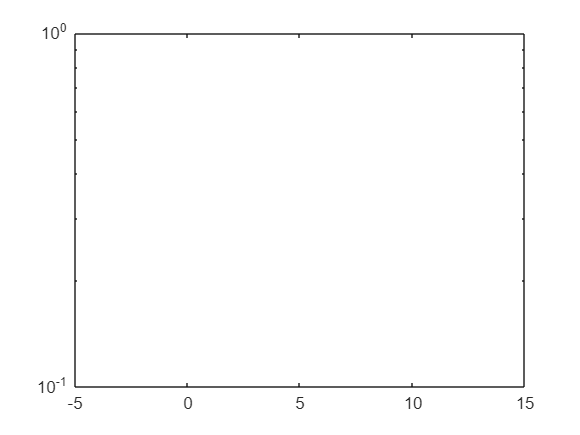


semilogy(SNR_range, P_PSS_ID) ;

% Simulation routine
% for run_number=1:n_runs
% Generate the time domain signal 
% Adding a time offset
% Adding a frequency offset
% Simulating a channel : AWGN + Rayleigh Fading 
% Finding the time offset : T0
% Finding the frequency offset : F0
% Report T0, F0
%end

- b. SSS Detection 

Function definitions :

function [x_t, PSS_iD, SSS_iD] = LTEsignalGen(num_sf)
    % Function that generates time domain samples of LTE signal consisting
    % of PSS and SSS synchronization signals.
    x_t = [] ;
    PSS_iD = randi([0, 2]) ;
    SSS_iD = randi([0, 15]) ;
    % Cell Settings : 
    enb.NDLRB = 6;                      % Number of resource blocks
    enb.CellRefP = 1;                   % One transmit antenna port
    enb.NCellID = 3*SSS_iD + PSS_iD;    % Cell ID
    enb.CyclicPrefix = 'Normal';        % Normal cyclic prefix
    enb.DuplexMode = 'FDD';             % FDD
    % Generation in frequency domain :
    txGrid = [] ;
    for i=0:num_sf - 1
        enb.NSubframe = mod(i, 10); % Subframe Index
        subframe = lteDLResourceGrid(enb);
        
        % Generate synchronizing signals
        pss_symbols = ltePSS(enb);
        sss_symbols = lteSSS(enb);
        antenna = 0 ;
        pssIndices = ltePSSIndices(enb, antenna);
        sssIndinces = lteSSSIndices(enb, antenna);
    
        % Map synchronizing signals to the grid
        subframe(pssIndices) = pss_symbols;
        subframe(sssIndinces) = sss_symbols;

        % Append subframe to grid to be transmitted
        txGrid = [txGrid subframe]; 
    end
    txGrid ;
    % Modulation : Conversion to time domain 
    [txWaveform,~] = lteOFDMModulate(enb,txGrid) ;
    x_t = [x_t txWaveform] ;
end

function [refPSS, refSSS] = refSignalGen(domain)
    % Function to generate the reference time domain or frequency domain
    % signals of the PSS and SSS for LTE.
    
    % Generation in frequency domain :
    refPSS = [] ;
    refSSS = [] ;
    if (domain == "time")
        % PSS sequences : 0 ~ 2 
        for PSS_id=0:2
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = PSS_id;  % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
            
            % Generate synchronizing signals
            pss_symbols = ltePSS(enb);
            pssIndices = ltePSSIndices(enb);
            
            PSSsubframe = lteDLResourceGrid(enb);
            PSSsubframe(pssIndices) = pss_symbols;

            % Modulation : Conversion to time domain 
            [t_pss,~] = lteOFDMModulate(enb,PSSsubframe) ;
            refPSS = [refPSS t_pss] ;
        end 
        % SSS sequences : 0 ~ 15
        for SSS_id=0:3:45
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = SSS_id;  % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
            
            % Generate synchronizing signals
            sss_symbols = lteSSS(enb);
            sssIndices = lteSSSIndices(enb);
            
            SSSsubframe = lteDLResourceGrid(enb);
            SSSsubframe(sssIndices) = sss_symbols;

            % Modulation : Conversion to time domain 
            [t_sss,~] = lteOFDMModulate(enb,SSSsubframe) ;
            refSSS = [refSSS t_sss] ;
        end
    else
        % PSS sequences : 0 ~ 2 
        for PSS_id=0:2
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = PSS_id;  % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
            
            % Generate synchronizing signals
            pss_symbols = ltePSS(enb);
            refPSS = [refPSS pss_symbols] ;
        end 
        % SSS sequences : 0 ~ 15
        for SSS_id=0:3:45
            enb.NDLRB = 6;                 % Number of resource blocks
            enb.CellRefP = 1;              % One transmit antenna port
            enb.NCellID = SSS_id;  % Cell ID
            enb.CyclicPrefix = 'Normal';   % Normal cyclic prefix
            enb.DuplexMode = 'FDD';        % FDD
            enb.NSubframe = 0; % Subframe Index
            
            % Generate synchronizing signals
            sss_symbols = lteSSS(enb);
            refSSS = [refSSS sss_symbols] ;
        end
    end
end
 
function [offset, ID] = myLTEreceiver(domain, rxSignal, refSignal, csi, isCoherentDet)
    % Function that detects and estimates the time and frequency offsets of
    % the impaired LTE signal.
end